# Transformée(s) de Hough - Espaces de votes

## I. Modélisation de segments de droite

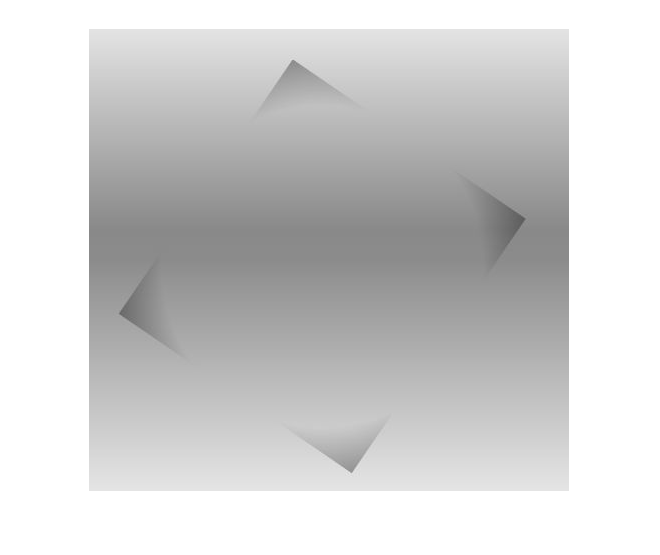

img=imread('TP03I01.jpg');
imshow(img);

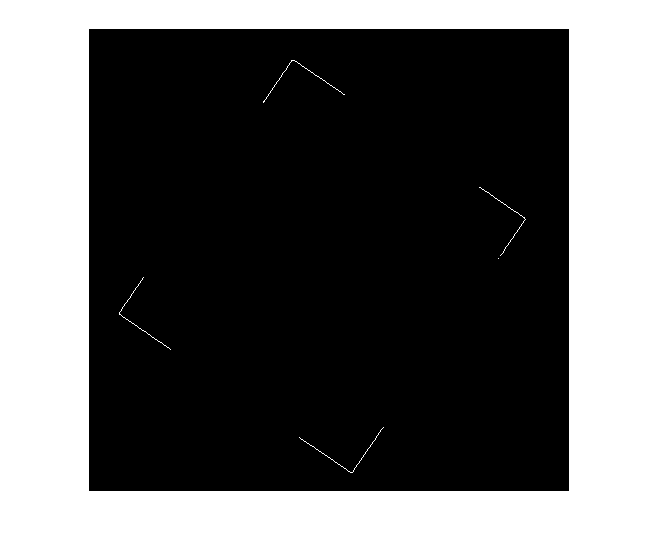

img=double(img);
threshold=7;
BW=edge(img,'Prewitt',threshold);
imshow(BW);

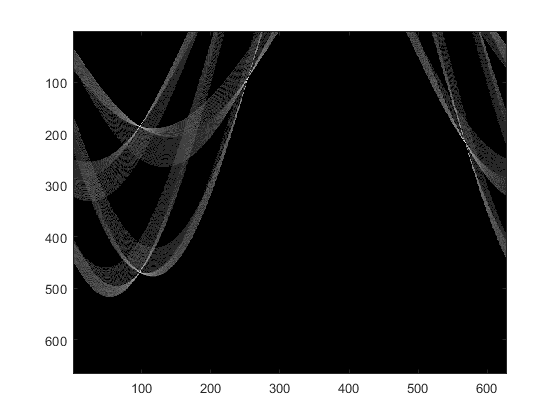

[x, y]=size(BW);
diag = round(sqrt(x.^2 + y.^2));
V = zeros(diag,628);
for i=1:x
    for j=1:y
      if (BW(i,j)==1)
        for teta=1:628        
            ro=round(i*cos(teta/100) + j*sin(teta/100)); 
            if(ro> 0 && ro < diag)
                V(ro,teta)=V(ro,teta)+1;
            end
        end
      end
    end
end
figure();
imagesc(log(V+1));
colormap(gray(256));

## II. Reconnaissance de segments de droite

Identifiez les coordonnées des k points recevant le plus grand nombre de votes

figure();
subplot(2,3,1);
imagesc(img);
title("Image de base")
axis equal;
axis off;

%------------------------------K=1--------------------------------
V_bis =V;
k = 1;
Liste_max = [];
for i=1:k
    [Vmax,idx]=max(V_bis);
    [Vmax, Vj] =max(Vmax);
    Vi = idx(Vj);
    Liste_max=[Liste_max; Vi Vj Vmax];
    V_bis(Vi, Vj) = 0;
end
Liste_max

Liste_max =    186    97    76


[row_v,col_v] = size(V);
epsilum = 0.2;
droites =[];

for indice=1 : size(Liste_max,1)
    bool = 0;
    rho = Liste_max(indice,1);
    theta = Liste_max(indice,2);
    for x=1:x
            for y=1:y
                if BW(x,y) == 1
                    if abs(x*cos(theta/100)+y*sin(theta/100)-rho) < epsilum
                        if bool == 0
                            x1 = x;
                            y1 = y;
                            bool = 1;
                        end
                           x2 = x;
                           y2= y;                           
                    end
                end
            end
    end
   droites =[droites ; y1 y2 x1 x2]; % Y  = col = abscisses
   %X = row = ordonnÃ©es
   
end
subplot(2,3,2);
hold on
imagesc(img);
colormap(gray(256));
for i= 1:size(droites,1)
        plot(droites(i,1:2),droites(i,3:4),'r-');
end
title("K=1")
hold off
axis equal;
axis off;
%------------------------------K=3--------------------------------
V_bis =V;
k = 3;
Liste_max = [];
for i=1:k
    [Vmax,idx]=max(V_bis);
    [Vmax, Vj] =max(Vmax);
    Vi = idx(Vj);
    Liste_max=[Liste_max; Vi Vj Vmax];
    V_bis(Vi, Vj) = 0;
end
Liste_max

Liste_max =    186    97    76
    90   254    63
   217   568    62


[row_v,col_v] = size(V);
epsilum = 0.2;
droites =[];

for indice=1 : size(Liste_max,1)
    bool = 0;
    rho = Liste_max(indice,1);
    theta = Liste_max(indice,2);
    for x=1:x
            for y=1:y
                if BW(x,y) == 1
                    if abs(x*cos(theta/100)+y*sin(theta/100)-rho) < epsilum
                        if bool == 0
                            x1 = x;
                            y1 = y;
                            bool = 1;
                        end
                           x2 = x;
                           y2= y;                           
                    end
                end
            end
    end
   droites =[droites ; y1 y2 x1 x2]; % Y  = col = abscisses
   %X = row = ordonnÃ©es
   
end
subplot(2,3,3);
hold on
imagesc(img);
colormap(gray(256));
for i= 1:size(droites,1)
        plot(droites(i,1:2),droites(i,3:4),'r-');
end 
title("K=3")
hold off
axis equal;
axis off;
%------------------------------K=4--------------------------------
V_bis =V;
k = 4;
Liste_max = [];
for i=1:k
    [Vmax,idx]=max(V_bis);
    [Vmax, Vj] =max(Vmax);
    Vi = idx(Vj);
    Liste_max=[Liste_max; Vi Vj Vmax];
    V_bis(Vi, Vj) = 0;
end
Liste_max

Liste_max =    186    97    76
    90   254    63
   217   568    62
   468    97    51


[row_v,col_v] = size(V);
epsilum = 0.2;
droites =[];

for indice=1 : size(Liste_max,1)
    bool = 0;
    rho = Liste_max(indice,1);
    theta = Liste_max(indice,2);
    for x=1:x
            for y=1:y
                if BW(x,y) == 1
                    if abs(x*cos(theta/100)+y*sin(theta/100)-rho) < epsilum
                        if bool == 0
                            x1 = x;
                            y1 = y;
                            bool = 1;
                        end
                           x2 = x;
                           y2= y;                           
                    end
                end
            end
    end
   droites =[droites ; y1 y2 x1 x2]; % Y  = col = abscisses
   %X = row = ordonnÃ©es
   
end
subplot(2,3,4);
hold on
imagesc(img);
colormap(gray(256));
for i= 1:size(droites,1)
        plot(droites(i,1:2),droites(i,3:4),'r-');
end
title("K=4")
hold off
axis equal;
axis off;
%------------------------------K=10--------------------------------
V_bis =V;
k = 10;
Liste_max = [];
for i=1:k
    [Vmax,idx]=max(V_bis);
    [Vmax, Vj] =max(Vmax);
    Vi = idx(Vj);
    Liste_max=[Liste_max; Vi Vj Vmax];
    V_bis(Vi, Vj) = 0;
end
Liste_max

Liste_max =    186    97    76
    90   254    63
   217   568    62
   468    97    51
    88   255    49
   220   569    46
   218   568    43
    95   253    42
    86   256    41
    86   255    40


[row_v,col_v] = size(V);
epsilum = 0.2;
droites =[];

for indice=1 : size(Liste_max,1)
    bool = 0;
    rho = Liste_max(indice,1);
    theta = Liste_max(indice,2);
    for x=1:x
            for y=1:y
                if BW(x,y) == 1
                    if abs(x*cos(theta/100)+y*sin(theta/100)-rho) < epsilum
                        if bool == 0
                            x1 = x;
                            y1 = y;
                            bool = 1;
                        end
                           x2 = x;
                           y2= y;                           
                    end
                end
            end
    end
   droites =[droites ; y1 y2 x1 x2]; % Y  = col = abscisses
   %X = row = ordonnÃ©es
   
end
subplot(2,3,5);
hold on
imagesc(img);
colormap(gray(256));
for i= 1:size(droites,1)
        plot(droites(i,1:2),droites(i,3:4),'r-');
end
title("K=10")
hold off
axis equal;
axis off;
%------------------------------K= 20--------------------------------
V_bis =V;
k = 20;
Liste_max = [];
for i=1:k
    [Vmax,idx]=max(V_bis);
    [Vmax, Vj] =max(Vmax);
    Vi = idx(Vj);
    Liste_max=[Liste_max; Vi Vj Vmax];
    V_bis(Vi, Vj) = 0;
end
Liste_max

Liste_max =    186    97    76
    90   254    63
   217   568    62
   468    97    51
    88   255    49
   220   569    46
   218   568    43
    95   253    42
    86   256    41
    86   255    40


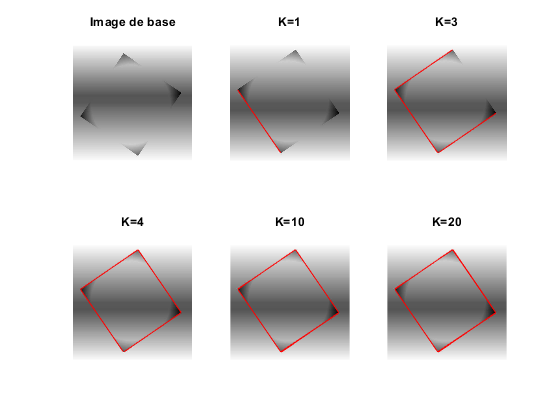

[row_v,col_v] = size(V);
epsilum = 0.2;
droites =[];

for indice=1 : size(Liste_max,1)
    bool = 0;
    rho = Liste_max(indice,1);
    theta = Liste_max(indice,2);
    for x=1:x
            for y=1:y
                if BW(x,y) == 1
                    if abs(x*cos(theta/100)+y*sin(theta/100)-rho) < epsilum
                        if bool == 0
                            x1 = x;
                            y1 = y;
                            bool = 1;
                        end
                           x2 = x;
                           y2= y;                           
                    end
                end
            end
    end
   droites =[droites ; y1 y2 x1 x2]; % Y  = col = abscisses
   %X = row = ordonnÃ©es
   
end
subplot(2,3,6);
hold on
imagesc(img);
colormap(gray(256));
for i= 1:size(droites,1)
        plot(droites(i,1:2),droites(i,3:4),'r-');
end
title("K=20")
hold off
axis equal;
axis off;

## III. Back projection of the Radon transform

% image2= double(imread('TP03I02.bmp'));
% I = zeros(468,500);
% for r = 1:468
%     for c = 1:500
%         for theta = 1:628
%             temp1 = ceil(r*cos(theta/100)+c*sin(theta/100));           
%             if( temp1 >0 && temp1 < 968)
%                 I(r,c) = I(r,c) + image2(temp1,theta);
%             end
%         end
%     end
%     disp(r);
% end
% figure();
% imagesc(I);
% colormap(gray(256));

## IV Generalized Hough Transform  

img=imread('TP03I03.bmp');
img=img(:,:,1)>0;
figure();
subplot(1,2,1)
imshow(img)
[r3,c3]=size(img);
Im_contour=zeros(r3,c3);
% Recovering information about the contour
[C, N]=contour(img);
for i=1:N
    Im_contour(C(i,1),C(i,2))=1;
end
subplot(1,2,2)
imshow(Im_contour);
% Initialize the model :
% row = beta value * 100
% column = order number of the couple (alpha, distance)
% third dimension: for 1 = alpha, for 2 = distance
H=zeros(round(100*2*pi),N,2);
% Calculation of the coordinates of the barycenter
[xo,yo]=barycentre(img);
hold on
scatter(yo,xo,'rx');
title("Contour & baricentre");
hold off
% Browsing the points on the contour
for i=1:N
    % calculation of b=beta for the ith point of the contour
    b=beta(C,img,i);
    b=round(b);
    % search for the first "empty" column in the table on the line beta
    k=1;
    while H(b+1,k,2)~=0
        k=k+1;
    end
    % record of the value of alpha and the distance on the b+1 row and the kth column of H
    a = alpha(C, i, img);
    d=distance(xo,yo,b,k);
    H(b+1,k,1)=a;
    H(b+1,k,2)=d;
end 


IV.3

figure();
subplot(1,2,1)
img=imread('TP03I03.bmp');
imshow(img);
threshold=7;
img_bin=edge(img,'Prewitt',threshold);
[x, y]=size(img_bin); 
diag = round(sqrt(x.^2 + y.^2));
V = zeros(diag,628);
for i=1:x
    for j=1:y
      if (img_bin(i,j)==1)
        for teta=1:628        
            ro=round(i*cos(teta/100) + j*sin(teta/100)); 
            if(ro> 0 && ro < diag)
                V(ro,teta)=V(ro,teta)+1;
            end
        end
      end
    end
end
subplot(1,2,2)
imagesc(log(V+1));
colormap(gray(256));
figure();
subplot(1,2,1)
img=imread('TP03I05.bmp');
img=img(:,:,1)>0;
imshow(img);
threshold=7;
img_bin=edge(img,'Prewitt',threshold);
[x, y]=size(img_bin); 
diag = round(sqrt(x.^2 + y.^2));
V = zeros(diag,628);
for i=1:x
    for j=1:y
      if (img_bin(i,j)==1)
        for teta=1:628        
            ro=round(i*cos(teta/100) + j*sin(teta/100)); 
            if(ro> 0 && ro < diag)
                V(ro,teta)=V(ro,teta)+1;
            end
        end
      end
    end
end
subplot(1,2,2)
imagesc(log(V+1));
colormap(gray(256));